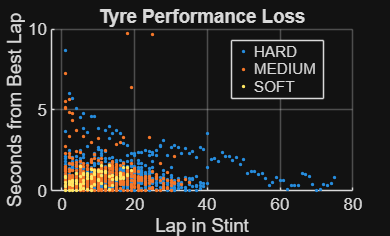

%% Setup
clear
clc
close all

T = readtable("data/clean_dataset.csv");

%% Create LapInStint

T = sortrows(T, {'Year','Event','Driver','Stint','LapNumber'});

groups = findgroups(T.Year,T.Event,T.Driver,T.Stint);

T.LapInStint = zeros(height(T),1);

for g = 1:max(groups)

    idx = find(groups==g);

    T.LapInStint(idx) = 1:length(idx);

end

%% Delta to Best Lap in Stint

groups = findgroups(T.Year,T.Event,T.Driver,T.Stint);

bestLap = splitapply(@min,T.LapTime,groups);

% Keep BestLap itself, not just the delta — needed later to
% reconstruct predicted absolute lap time from a predicted delta
T.BestLap = bestLap(groups);
T.DeltaBestLap = T.LapTime - T.BestLap;

figure

gscatter(T.LapInStint,...
    T.DeltaBestLap,...
    T.Compound)

xlabel("Lap in Stint")
ylabel("Seconds from Best Lap")
title("Tyre Performance Loss")
grid on


T.FuelNorm = T.FuelEstimate / max(T.FuelEstimate);

writetable(T,"data/engineered_dataset.csv")

fprintf("engineered_dataset.csv written: %d rows\n", height(T))

engineered_dataset.csv written: 1616 rows
